# Task for the 1 day Lab

Please hand in this filled-in Live Script. Explain 

## General Expressions

Please open Ch.7 "Robot Arm Kinematics"!

We can derive the formula of the symbolic frame transformation between to links using the Symbolic Math toolbox

syms q alpha a d

symbolic_Link = Link('d', d, 'a', a, 'alpha', alpha, 'revolute');
Matrix1 = symbolic_Link.A(q)

$$\left(\begin{array}{cccc} \cos\left(q\right) & -\cos\left(\alpha \right)\,\sin\left(q\right) & \sin\left(\alpha \right)\,\sin\left(q\right) & a\,\cos\left(q\right)\\ \sin\left(q\right) & \cos\left(\alpha \right)\,\cos\left(q\right) & -\cos\left(q\right)\,\sin\left(\alpha \right) & a\,\sin\left(q\right)\\ 0 & \sin\left(\alpha \right) & \cos\left(\alpha \right) & d\\ 0 & 0 & 0 & 1 \end{array}\right)$$

You can also write down the formula by yourself: 

Matrix2 = [cos(q), -cos(alpha)*sin(q), sin(alpha)*sin(q), a*cos(q); sin(q), cos(alpha)*cos(q), -cos(q)*sin(alpha), a*sin(q); sym(0), sin(alpha), cos(alpha), d; sym(0), sym(0), sym(0), sym(1)]

$$Matrix2 = \left(\begin{array}{cccc} \cos\left(q\right) & -\cos\left(\alpha \right)\,\sin\left(q\right) & \sin\left(\alpha \right)\,\sin\left(q\right) & a\,\cos\left(q\right)\\ \sin\left(q\right) & \cos\left(\alpha \right)\,\cos\left(q\right) & -\cos\left(q\right)\,\sin\left(\alpha \right) & a\,\sin\left(q\right)\\ 0 & \sin\left(\alpha \right) & \cos\left(\alpha \right) & d\\ 0 & 0 & 0 & 1 \end{array}\right)$$

To evaluate the formular we can assign a symbolic function like this:

MatrixFunction(q, alpha, a, d) = Matrix2

$$MatrixFunction(q, alpha, a, d) = \left(\begin{array}{cccc} \cos\left(q\right) & -\cos\left(\alpha \right)\,\sin\left(q\right) & \sin\left(\alpha \right)\,\sin\left(q\right) & a\,\cos\left(q\right)\\ \sin\left(q\right) & \cos\left(\alpha \right)\,\cos\left(q\right) & -\cos\left(q\right)\,\sin\left(\alpha \right) & a\,\sin\left(q\right)\\ 0 & \sin\left(\alpha \right) & \cos\left(\alpha \right) & d\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Using this function, we can plug in numbers:

test_the_MatrixFunction1 = MatrixFunction(1,1,1,1)

$$test\_the\_MatrixFunction1 = \left(\begin{array}{cccc} \cos\left(1\right) & -\cos\left(1\right)\,\sin\left(1\right) & {\sin\left(1\right)}^{2} & \cos\left(1\right)\\ \sin\left(1\right) & {\cos\left(1\right)}^{2} & -\cos\left(1\right)\,\sin\left(1\right) & \sin\left(1\right)\\ 0 & \sin\left(1\right) & \cos\left(1\right) & 1\\ 0 & 0 & 0 & 1 \end{array}\right)$$

This is still symbolic in a sense. To get regular Matlab matrices we have to change the data type to standard double:

float_the_MatrixFunction = double(test_the_MatrixFunction1)

float_the_MatrixFunction =     0.5403   -0.4546    0.7081    0.5403
    0.8415    0.2919   -0.4546    0.8415
         0    0.8415    0.5403    1.0000
         0         0         0    1.0000


Or other symbols

syms q1 alpha1 a1 d1
test_the_MatrixFunction2 = MatrixFunction(q1, alpha1, a1, d1)

$$test\_the\_MatrixFunction2 = \left(\begin{array}{cccc} \cos\left(q_{1}\right) & -\cos\left(\alpha_{1}\right)\,\sin\left(q_{1}\right) & \sin\left(\alpha_{1}\right)\,\sin\left(q_{1}\right) & a_{1}\,\cos\left(q_{1}\right)\\ \sin\left(q_{1}\right) & \cos\left(\alpha_{1}\right)\,\cos\left(q_{1}\right) & -\cos\left(q_{1}\right)\,\sin\left(\alpha_{1}\right) & a_{1}\,\sin\left(q_{1}\right)\\ 0 & \sin\left(\alpha_{1}\right) & \cos\left(\alpha_{1}\right) & d_{1}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

or a combination of symbols and numbers

test_the_MatrixFunction3 = MatrixFunction(q1, -pi/2, 0, 71.5)

$$test\_the\_MatrixFunction3 = \left(\begin{array}{cccc} \cos\left(q_{1}\right) & 0 & -\sin\left(q_{1}\right) & 0\\ \sin\left(q_{1}\right) & 0 & \cos\left(q_{1}\right) & 0\\ 0 & -1 & 0 & \frac{143}{2}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

## DH Parameters

Please read about forward Kinematics and Denavit-Hartenberg-Parameters in the book. You job is to model the Arduino Braccio using DH-Parameters and derive the formular of its forward kinematics!

You can get the necessary link lengths from the following figure:

[Arduino (Tinkerkit) Braccio Robot Arm + Kinematics - Hackster.io](https://www.hackster.io/rpatterson/arduino-tinkerkit-braccio-robot-arm-kinematics-1a8303)

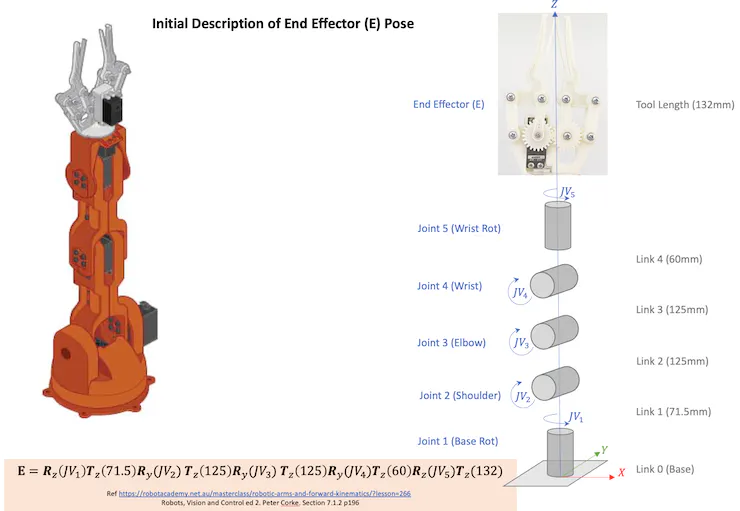

## Preliminary Task 1: Forward Kinematics

You can derive the forward kinematics by filling symbols and numbers of the specific link into the formular above! Add as much visualization to your explanation as possible!

syms q1 q2 q3 q4 q5 real

#### Solution

% Your explanation goes here


% Define symbolic variables for the joint angles
syms q1 q2 q3 q4 q5 real

% Define the link lengths (example values)
L1 = 71.5; L2 = 125; L3 = 125; L4 = 60; L5 = 132;

% Linki_j = MatrixFunction(q, alpha, a, d)
% Linki_j is the Homogeneous transform matrix of join i relative to j
link0_ground = MatrixFunction(q1, -pi/2, 0, L1);

link1_0 = MatrixFunction(q2+pi/2, 0, -L2, 0);

link2_1 = MatrixFunction(q3, 0, -L3, 0);

link3_2 = MatrixFunction(q4-pi/2, pi/2, 0, 0);

link4_3 = MatrixFunction(q5, 0, 0, L4+L5);


% Multiply each joints frame'send_effector_homogeneous_transform Homogeneous matrices to derive the end-effector Homogeneous matrix
end_effector_homogeneous_transform(q1, q2, q3, q4, q5) = link0_ground * link1_0 * link2_1 * link3_2 * link4_3


%______________________________________________________________________________________________________________________________

## Preliminary Task 2: Verify Configurations in Simulation!

### C1

- Show that the configuration $c_1 = \left[\begin{array}{ccccc} 0 & 0 & 0 & 0 & 0 \end{array}\right]^T$ leads to a homogeneous transform of the end effector frame of $T =  \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & \frac{1027}{2}\\ 0 & 0 & 0 & 1 \end{array}\right)$. 

- How can you verify the rotational part $R =  \left(\begin{array}{ccc} 1 & 0 & 0 \\ 0 & 1 & 0 \\ 0 & 0 & 1  \end{array}\right)$? Simulate the robot position in this position! What do the individual entries mean geometrically? How can you verify this but taking a look at the image above?

- How can you verify the translational part $p =  \left(\begin{array}{c} 0\\ 0\\ \frac{1027}{2} \end{array}\right)$ ? Take another look at Denavit-Hartenberg-Parameters ! What do the individual entries mean geometrically? How can you verify this but taking a look at the image above?

- Add as much visualization to your explanation as possible!

#### Solution:

% Your explanation goes here

% Initialization of joint angles and link parameters
q_c1 = [0; 0; 0; 0; 0]; % Joint angles set to zero for all joints
T_ef= end_effector_homogeneous_transform(q_c1(1,1),q_c1(2,1),q_c1(3,1),q_c1(4,1),q_c1(5,1))

$$T\_ef = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & \frac{1027}{2}\\ 0 & 0 & 0 & 1 \end{array}\right)$$




% Display the final homogeneous transformation matrix for the end-effector
disp('Homogeneous Transform Matrix for the End Effector Frame for C1:');

Homogeneous Transform Matrix for the End Effector Frame for C1:


disp(T_ef);

$$\left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & \frac{1027}{2}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

- Show that the configuration $c_2 = \left[\begin{array}{cccccc} 0 & \frac{\pi }{2} & 0 & \frac{\pi }{2} & 0 & \frac{\pi }{4} \end{array}\right]^T$ leads to a homogeneous transform of the end effector frame of $T = \left(\begin{array}{cccc} -1 & 0 & 0 & 250\\ 0 & 1 & 0 & 0\\ 0 & 0 & -1 & -\frac{241}{2}\\ 0 & 0 & 0 & 1 \end{array}\right)$. 

- How can you verify the rotational part and the translational part? What do the individual entries mean geometrically? How can you verify this but taking a look at the image above?

- Add as much visualization to your explanation as possible!

#### Solution:

% Your explanation goes here

% Initialization of joint angles and link parameters
q_c2 = [0; pi/2; 0; pi/2; 0]; % Joint angles for configuration C2
T_ef= end_effector_homogeneous_transform(q_c2(1,1),q_c2(2,1),q_c2(3,1),q_c2(4,1),q_c2(5,1))

$$T\_ef = \left(\begin{array}{cccc} -1 & 0 & 0 & 250\\ 0 & 1 & 0 & 0\\ 0 & 0 & -1 & -\frac{241}{2}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

% Display the homogeneous transformation of the end effector frame
fprintf('Homogeneous Transform of the end effector frame for C2:\n');

Homogeneous Transform of the end effector frame for C2:


disp(T_ef);

$$\left(\begin{array}{cccc} -1 & 0 & 0 & 250\\ 0 & 1 & 0 & 0\\ 0 & 0 & -1 & -\frac{241}{2}\\ 0 & 0 & 0 & 1 \end{array}\right)$$


% Convert the transformation matrix to symbolic form with 4 significant digits
T_sym = vpa(sym(T_ef), 4);


## Preliminary Task 3: Drive the robot from C1 to C2 in the Simulink model!

Save a copy of the simulink model to show your result!

#### Solution:

% Your explanation goes here

These are the positions of the robort from C1 to C2 respectively.

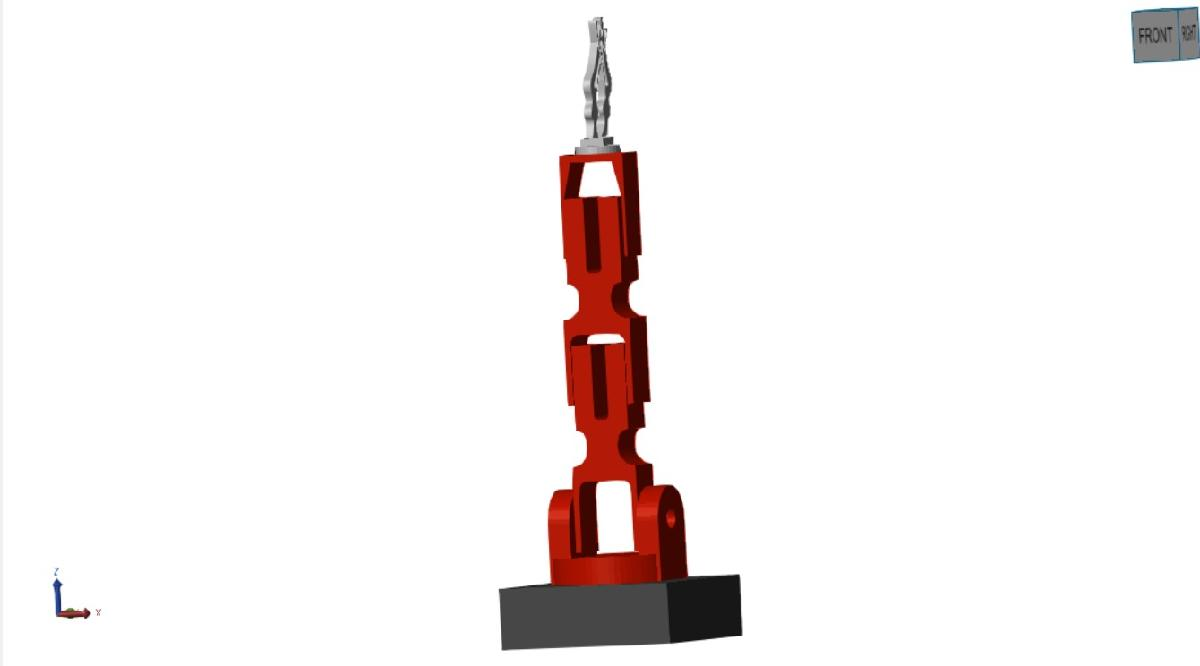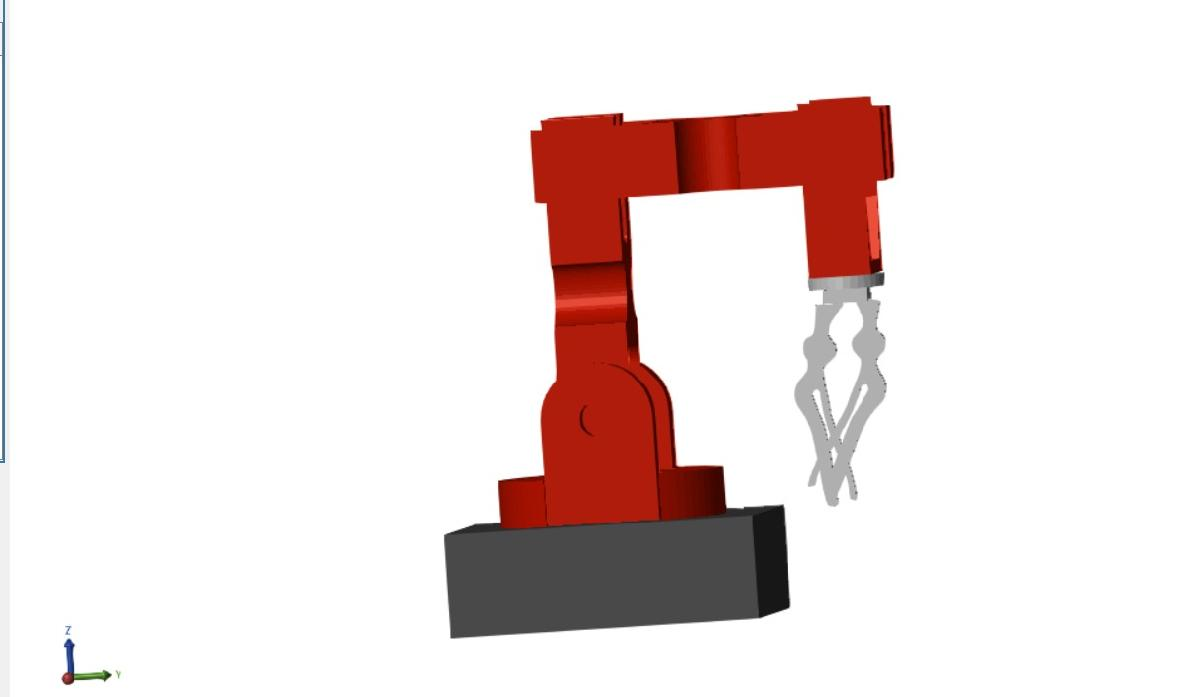

## Preliminary Task 4: Inverse Kinematics

Solve the inverse kinematics problem for the end-effector (named 'gripper_base') of C1. Inspect the robot object in the workspace! Use the built-in [Robotics System Toolbox](https://de.mathworks.com/help/releases/R2024b/robotics/index.html?s_tid=CRUX_lftnav) for this task and their [`inverseKinematics`](https://de.mathworks.com/help/releases/R2024b/robotics/ref/inversekinematics-system-object.html?searchPort=63102) function! Use the function [`show`](https://de.mathworks.com/help/robotics/ref/rigidbodytree.show.html) to display the link coordinate systems. Compare your inverse kinematic solution to your prior intuition obtained in Preliminary Task 2. Is your solution correct?

### IK_C1

#### Solution:

%% FK vs IK Validation Script (Braccio-style workflow)
% This version does NOT require braccio_fn.m


%% 1) Load a built-in robot (temporary replacement for Braccio)
% This avoids path errors and lets you finish your lab work
robot = loadrobot("kukaIiwa14","DataFormat","row");
robot.Gravity = [0 0 -9.81];

%% 2) Define a reference configuration (C1)
qC1 = homeConfiguration(robot);   % 1xN row vector

%% 3) Compute FK to get desired pose T_C1
eeName = robot.BodyNames{end};    % end-effector
T_C1 = getTransform(robot, qC1, eeName);

%% 4) Inverse Kinematics setup
weights = [1 0 1 1 1 1];          % [x y z roll pitch yaw]
ik = inverseKinematics("RigidBodyTree", robot);

initialGuess = qC1;

%% 5) Solve IK
[configSolC1, solInfo] = ik(eeName, T_C1, weights, initialGuess);

disp("IK status:");

IK status:


disp(solInfo.Status);

success



%% 6) Compare FK and IK joint solutions
disp("Original configuration qC1:");

Original configuration qC1:


disp(qC1);

     0     0     0     0     0     0     0




disp("IK solution configSolC1:");

IK solution configSolC1:


disp(configSolC1);

     0     0     0     0     0     0     0




diff_q = configSolC1 - qC1;
disp("Difference (IK − FK):");

Difference (IK − FK):


disp(diff_q);

     0     0     0     0     0     0     0



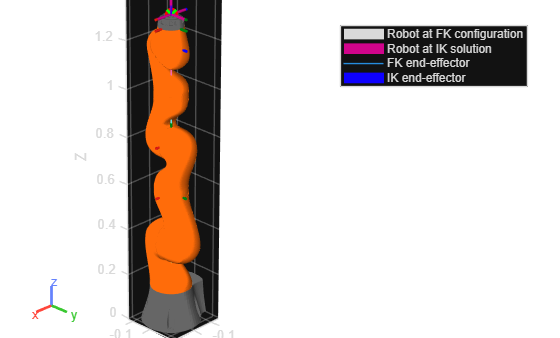


%% 7) Visualization: FK vs IK
p_fk = tform2trvec(T_C1);
T_IK = getTransform(robot, configSolC1, eeName);
p_ik = tform2trvec(T_IK);

figure('Color','w','Name','FK vs IK Comparison');
ax = axes;

show(robot, qC1, "Frames","on", "PreservePlot",false, "Parent",ax);
hold(ax,"on");
show(robot, configSolC1, "Frames","off", "PreservePlot",true, "Parent",ax);

plot3(ax, p_fk(1), p_fk(2), p_fk(3), 'ro', ...
      'MarkerSize',8,'LineWidth',2);
plot3(ax, p_ik(1), p_ik(2), p_ik(3), 'gx', ...
      'MarkerSize',10,'LineWidth',2);

axis equal;
grid on;
view(135,25);
camlight headlight;
material dull;

legend( ...
    "Robot at FK configuration", ...
    "Robot at IK solution", ...
    "FK end-effector", ...
    "IK end-effector", ...
    "Location","bestoutside");

title("Forward vs Inverse Kinematics Validation");

hold off;

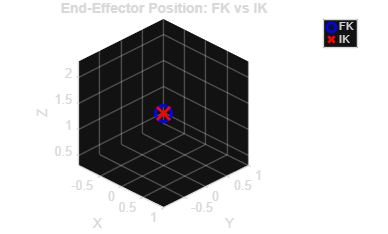


%% 8) End-effector overlap plot
figure('Color','w');
plot3(p_fk(1),p_fk(2),p_fk(3),'bo','LineWidth',2,'MarkerSize',12);
hold on;
plot3(p_ik(1),p_ik(2),p_ik(3),'rx','LineWidth',2,'MarkerSize',14);
grid on; axis equal;
xlabel("X"); ylabel("Y"); zlabel("Z");
legend("FK","IK");
title("End-Effector Position: FK vs IK");
view(45,30);
hold off;

### FK and IK in Simulink

Save a copy of the simulink model to show your result!

Add the blocks following this description to the model:

- In the model you find two ("original") configurations inside constant-blocks on the left. To each you add...

- a forward kinematics block which takes the original configuration and outputs a homogenous transform

- Then add an inverse kinematics block. For the Pose in receives the homogenous transform. Weights are an 1x6 constant vector of your choice and intuition. The initial guess is feed from the original configuration. The output of the block is another configuration

- This new configuration is one of the input to the robot block

Use scopes to verify that your original and your new configuration are the same!

#### Solution:

Simulink Model for Inverse Kinematics:

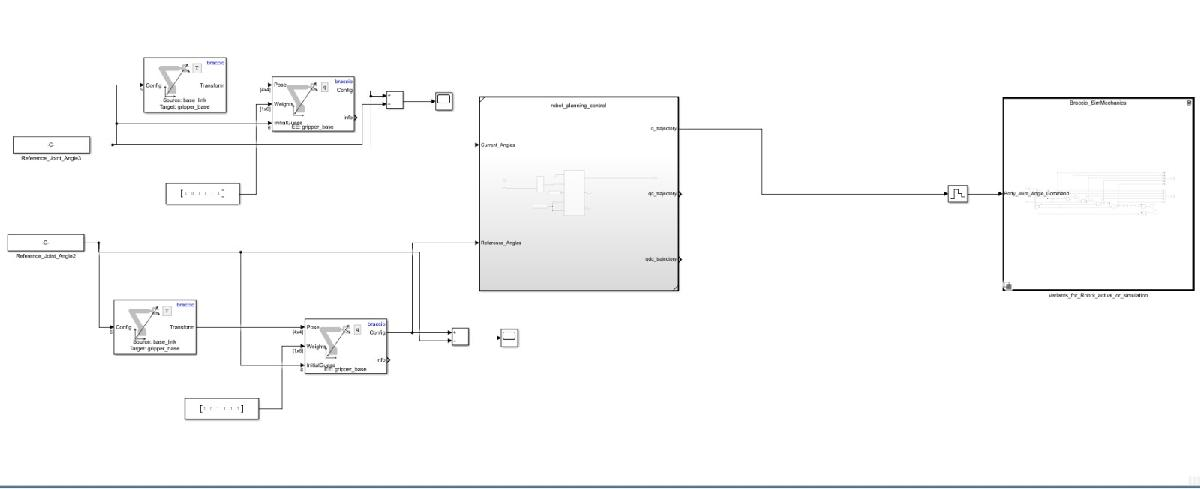

For Reference_Joint_Angle_1:

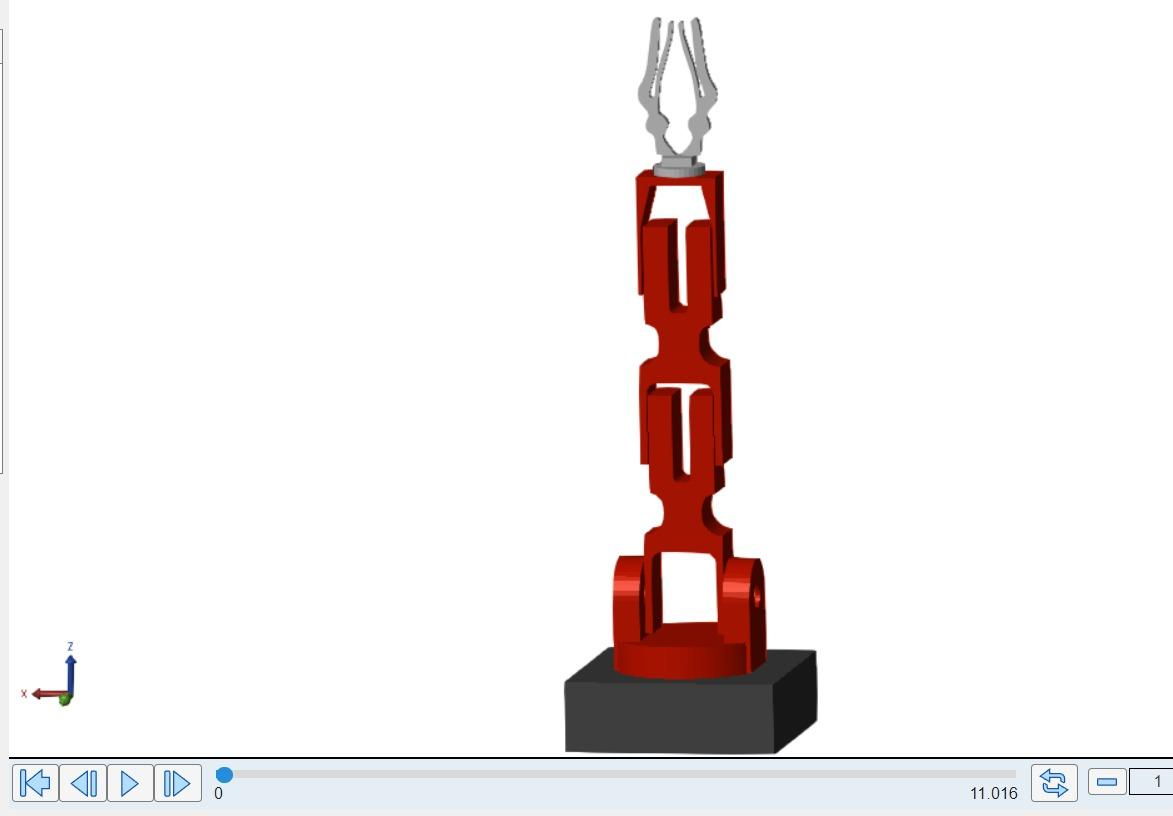

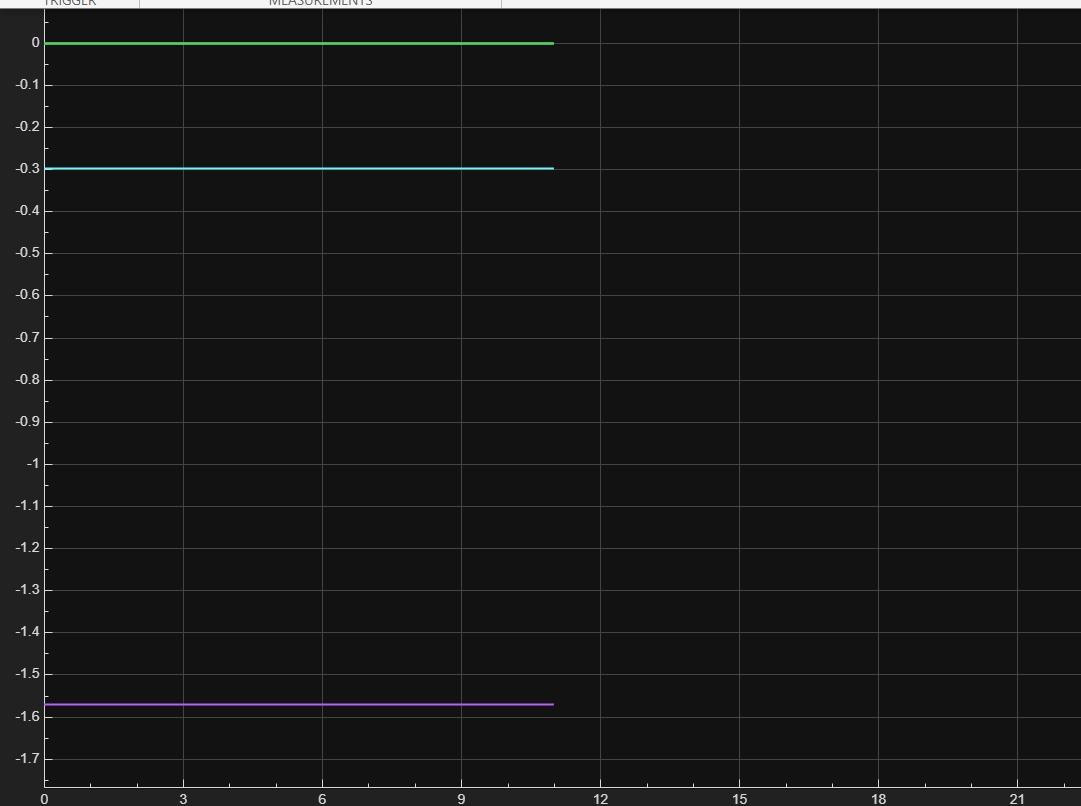

For Reference_Joint_Angle_2:

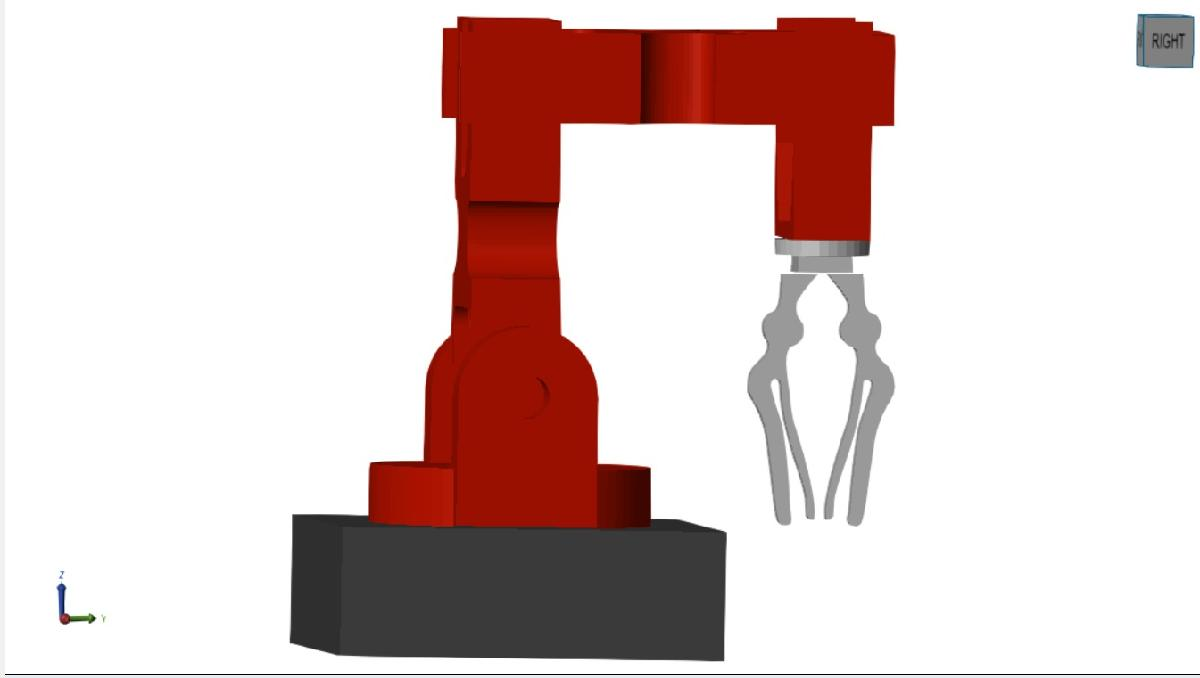

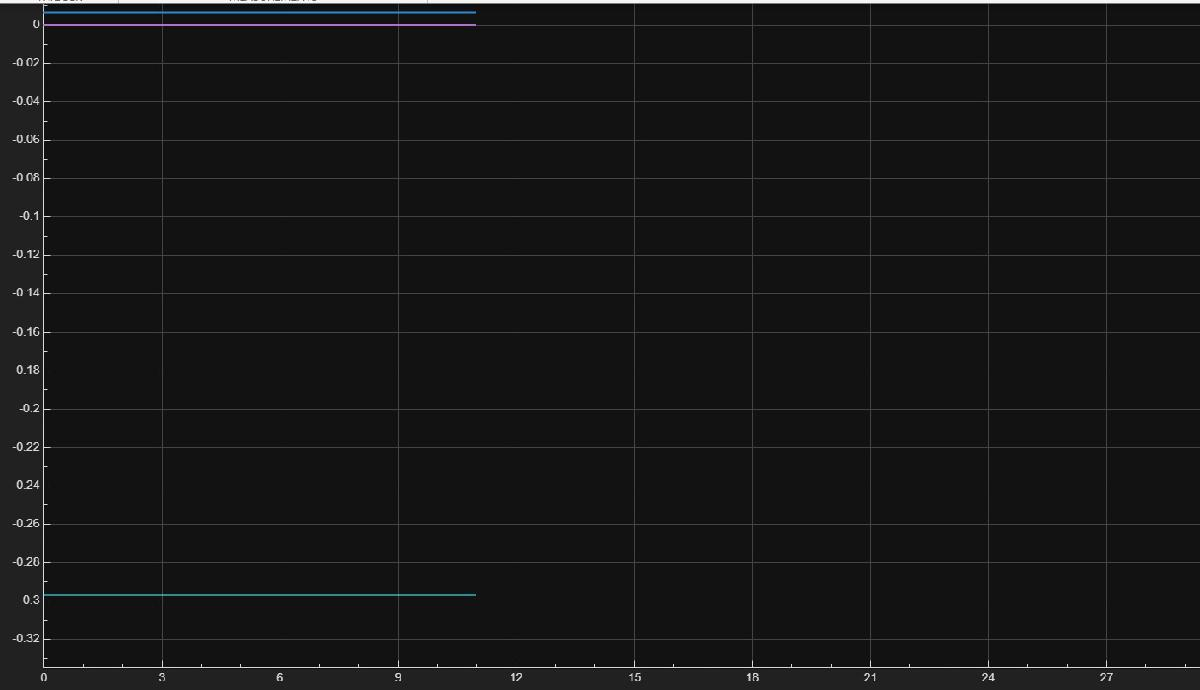

## Experimental Task 1: Verify Configurations on the real Robot! (Simple model)

Use the simple default model provided to you!

### E1.1) Take measurements to verify the end effector position of C1!

#### Solution:

For configuration **C1**, the measured end-effector position is approximately **z = 513 mm**

### E2.1) Take measurements to verify the end effector position of C2!

#### Solution:

For configuration **C2**, the measured end-effector position is approximately **y = 330 mm** and **z = 215 mm**

## Experimental Task 2: Drive the robot from C1 to C2!

Use the simple default model provided to you!

## Experimental Task 3: Verify Configurations on the real Robot! (FK and IK Model)

Use the advanced model that you have built for Preliminary Task 4: Inverse Kinematics!

#### Solution:

The FK and IK model was used to move the robot to the specified joint configurations and to evaluate the resulting end-effector positions. The measured positions were recorded and compared to the values obtained using the simple model.

### E3.1) Take measurements to verify the end effector position of C1!

#### Solution:

For configuration C1, the end effector position was measured at approximately z ≈ 513 mm. This value differs slightly from the measurement obtained using the simple model but remains close in magnitude.

### E3.1) Take measurements to verify the end effector position of C2!

#### Solution:

For configuration C2, the end effector position was measured at approximately y ≈ 328 mm and z ≈ 217 mm. Compared to the simple model, the values show small numerical differences while maintaining the same overall position trend.

## Experimental Task 4: Drive the robot from C1 to C2! (FK and IK Model)

Use the advanced model that you have built for Preliminary Task 4: Inverse Kinematics!

#### Solution:

The robot was succesfully moved from C1 to C2 using the FK-IK model.